%個体ファイル
root_path="E:\project\Data\3D_sensor_data";
inv_dir=get_dir(root_path);
%日付ファイル
path="E:\project\Data\3D_sensor_data\"+inv_dir(20).name;
date_dir=get_dir(path);
%CSVファイル
csv_path = path +'\'+date_dir(1).name;
files = get_dir(csv_path);

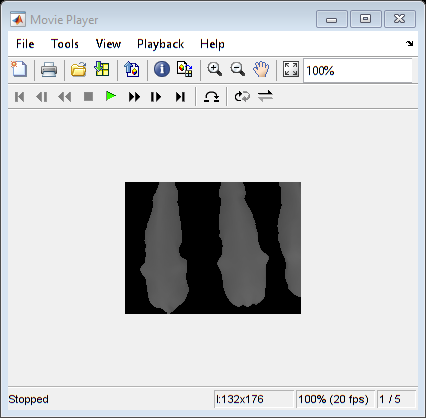

a =1;
seq_img=csv2img2(csv_files,3);
norm_seq=nd(seq_img,3);
norm_clean_BW=clean_image(norm_seq,0,1);
norm_clean_seq=(norm_clean_BW>0.3).*norm_clean_BW;
implay(norm_clean_seq)

# **preprocessing**

[csv_files,name]=get_cow(1);
inv_cow=invcow(csv_files);
resizedcow=hip(inv_cow);

%save files  39,20
for i=40:41
    i
    [csv_files,name]=get_cow(i);
    inv_cow=invcow(csv_files);
    resizedcow=hip(inv_cow);
    mkdir("../data/"+name)
        
    for j=1:size(resizedcow,2)
        csvwrite("../data/"+name+"/"+name+"_"+(j)+".csv",resizedcow(j).img);
    end
    
end

i = 40

i = 41

Index exceeds the number of array elements (40).

Error in get_cow (line 9)
    name=inv_dir(a).name;

# **feature**

vec(40).mean=[];
for j=1:40
    
    if j==20||j==39
        continue
    end
    
    %j番目の個体のcsvファイルを読み取る
    [csv_files,name]=get_cow(j);    
    inv_cow=invcow(csv_files);
    resizedcow=hip(inv_cow);
    
    %最大値の平均を求める.
    siz=size(resizedcow,2);
    su=zeros(1,71);
    
    for i=1:siz
        img=resizedcow(i).img;
        [~,~,ma]=maxplot(img);
        su=su+ma;
    end
    
    su=su./siz;
    vec(j).mean=exp(su);
end

# **Result**

X=inv_cow(1).seq;
I=predictcow(X,vec)

I = 7

# **write data**

for i=1:40
    J=0;
    n=get_size(i);
    for m=1:n
        [csv_files,name]=get_cow(i,m);
        
        if isa(csv_files,"struct")
            
            if m==1
                mkdir("../data/"+name)
            end
            
            mem=invcow(csv_files);
            
            for j=1:size(mem,2)
                csvwrite("../data/"+name+"/"+name+"_"+(j+J)+".csv",mem(j).seq);
            end
            J=J+size(mem,2);
            
        end
        
    end
    
end

出力引数 "mem" (および他の引数もおそらく) は "invcow" の呼び出し中に代入されていません。